# MATLAB Beginner Live Script

## Variables and basic operations

a = 5;
b = 2;
c = a + b

c = 7

d = a * b

d = 10

## Arrays and indexing

x = [1 2 3 4 5]

x =      1     2     3     4     5


y = x(2:4)

y =      2     3     4


z = linspace(0, 1, 10)

z =          0    0.1111    0.2222    0.3333    0.4444    0.5556    0.6667    0.7778    0.8889    1.0000


## Conditional statements

if a > b
    disp('a is greater than b');
elseif a < b
    disp('a is less than b');
else
    disp('a is equal to b');
end

a is greater than b


## Loops

for i = 1:5
    disp(['Iteration ' num2str(i)]);
end

Iteration 1
Iteration 2
Iteration 3
Iteration 4
Iteration 5


## Functions

result = myFunction(a, b);
disp(['Result = ' num2str(result)]);

Result = 29


## Plotting

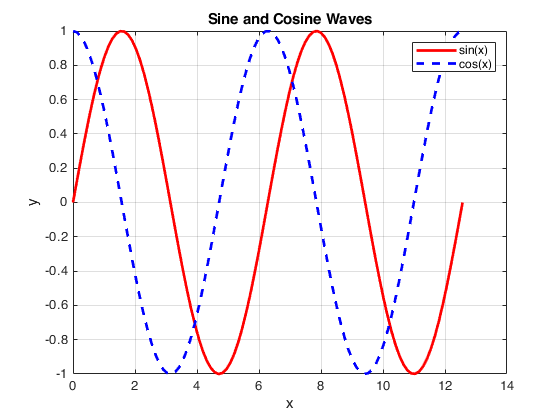

x = linspace(0, 4*pi, 100);
y1 = sin(x);
y2 = cos(x);
figure;
plot(x, y1, 'r', 'LineWidth', 2);
hold on;
plot(x, y2, 'b--', 'LineWidth', 2);
title('Sine and Cosine Waves');
xlabel('x');
ylabel('y');
legend('sin(x)', 'cos(x)');
grid on;

## Symbolic Toolbox Example

% Define symbolic variables
syms x y;

% Define symbolic expressions
expr1 = x^2 + 2*x + 1

$$expr1 = x^{2}+2\,x+1$$

expr2 = sin(x)^2 + cos(x)^2

$$expr2 = {\cos\left(x\right)}^{2}+{\sin\left(x\right)}^{2}$$

expr3 = diff(expr1, x)

$$expr3 = 2\,x+2$$

% Evaluate expressions at specific values
eval1 = subs(expr1, x, 3)

$$eval1 = 16$$

eval2 = subs(expr2, x, pi/4)

$$eval2 = 1$$

% Simplify expressions
simplified_expr1 = simplify(expr1)

$$simplified\_expr1 = {\left(x+1\right)}^{2}$$

simplified_expr2 = simplify(expr2)

$$simplified\_expr2 = 1$$

% Solve equations symbolically
eqn = x^2 - 4 == 0

$$eqn = x^{2}-4=0$$

sol = solve(eqn, x)

$$sol = \left(\begin{array}{c} -2\\ 2 \end{array}\right)$$

% Perform symbolic integration
integral_expr = int(expr1, x)

$$integral\_expr = \frac{x\,\left(x^{2}+3\,x+3\right)}{3}$$

## Matrix Inversion Example

% Define symbolic variables
syms a b c d;

% Define a symbolic matrix
A = [a, b; c, d]

$$A = \left(\begin{array}{cc} a & b\\ c & d \end{array}\right)$$

% Compute the inverse of the matrix
invA = inv(A)

$$invA = \left(\begin{array}{cc} \frac{d}{a\,d-b\,c} & -\frac{b}{a\,d-b\,c}\\ -\frac{c}{a\,d-b\,c} & \frac{a}{a\,d-b\,c} \end{array}\right)$$

% Assign values to the symbolic variables
a_val = 2;
b_val = 3;
c_val = 1;
d_val = 4;

% Substitute the values in the matrix
A_val = subs(A, [a, b, c, d], [a_val, b_val, c_val, d_val])

$$A\_val = \left(\begin{array}{cc} 2 & 3\\ 1 & 4 \end{array}\right)$$

% Substitute the values in the inverse matrix
invA_val = subs(invA, [a, b, c, d], [a_val, b_val, c_val, d_val])

$$invA\_val = \left(\begin{array}{cc} \frac{4}{5} & -\frac{3}{5}\\ -\frac{1}{5} & \frac{2}{5} \end{array}\right)$$

## Simple Low-Pass Filter Design Example

% Filter specifications
cutoff_freq = 1000;          % Cut-off frequency in Hz
sampling_freq = 8000;       % Sampling frequency in Hz
filter_order = 6;           % Filter order

% Create a low-pass filter
[b, a] = butter(filter_order, cutoff_freq/(sampling_freq/2), 'low')

b =     0.0011    0.0063    0.0158    0.0210    0.0158    0.0063    0.0011


a =     1.0000   -2.9785    4.1361   -3.2598    1.5173   -0.3911    0.0434


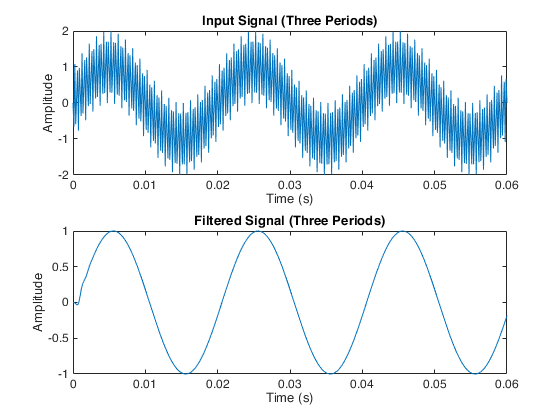

% Generate a test input signal
t = 0:1/sampling_freq:3/50;  % Time vector for three periods of 50 Hz signal
f1 = 50;                    % Frequency of the 50 Hz signal
f2 = 5000;                  % Frequency of the 5 kHz signal
x = sin(2*pi*f1*t) + sin(2*pi*f2*t); % Input signal (sum of sine waves)

% Apply the filter to the input signal
y = filter(b, a, x);

% Plot the input and filtered signals
figure;
subplot(2, 1, 1);
plot(t, x);
xlabel('Time (s)');
ylabel('Amplitude');
title('Input Signal (Three Periods)');

subplot(2, 1, 2);
plot(t, y);
xlabel('Time (s)');
ylabel('Amplitude');
title('Filtered Signal (Three Periods)');